it=1;
clc
disNeuronas=0;
Nindividuos=100;
Nciudades=10;
PNelitismo=0.1;
PNMutacion=0.02;
NMutacion=PNMutacion*Nindividuos;
PNtorneos=0.2;
Ntorneos=PNtorneos*Nindividuos;
x0=0;
y0=0;
xf=15;
yf=15;
Po=[x0; y0];
Pf=[xf; yf];
Ciudades=rand(2, Nciudades);
Ciudades(1,:)=rescale(Ciudades(1, :), 0, 15)

Ciudades =     4.3556    6.5503         0    5.5629   13.8344    5.3600   14.8491   15.0000    4.7442    7.6210
    0.6353    0.4911    0.4862    0.8803    0.2638    0.4642    0.9567    0.3552    0.8675    0.6809


Ciudades(2,:)=rescale(Ciudades(2, :), 0, 15)

Ciudades =     4.3556    6.5503         0    5.5629   13.8344    5.3600   14.8491   15.0000    4.7442    7.6210
    8.0426    4.9219    4.8161   13.3453         0    4.3384   15.0000    1.9797   13.0683    9.0308


Individuos=zeros(Nindividuos, Nciudades);
for i=1:Nindividuos
    Individuos(i, :)=randperm(Nciudades, Nciudades);
end
Individuos;
Ganador=zeros(2, Nciudades);
Bondad=zeros(Nindividuos, 1);
Nelitismo=(PNelitismo*Nindividuos);
Ncruzamientos=(Nindividuos-Nelitismo)/2;

while it<900
    for r=1:Nindividuos
        Prebondad=(Po(1)-Ciudades(1, Individuos(r, 1)))^2+(Po(2)-Ciudades(2, Individuos(r, 1)))^2;
        for k=2:Nciudades
            Prebondad=(Ciudades(1, Individuos(r, k-1))-Ciudades(1, Individuos(r, k)))^2+(Ciudades(2, Individuos(r, k-1))-Ciudades(2, Individuos(r, k)))^2+Prebondad;
        end
        Prebondad=(Pf(1)-Ciudades(1, Individuos(r, Nciudades)))^2+(Pf(2)-Ciudades(2, Individuos(r, Nciudades)))^2+Prebondad;
        Bondad(r)=sqrt(Prebondad);
    end
    [BondadOrdenada, IndBondad]=sort(Bondad);
    IndElitismo=IndBondad(1:Nelitismo);
    Elite=Individuos(IndElitismo, :);
    Hijos=[];
    for t=1:Ncruzamientos
        TorneoPadre=randperm(Nindividuos, Ntorneos);
        PrePadre=intersect(IndBondad, TorneoPadre, 'stable');
        Padre=PrePadre(1);
        TorneoMadre=randperm(Nindividuos, Ntorneos);
        PreMadre=intersect(IndBondad, TorneoMadre, 'stable');
        Madre=PreMadre(1);
        lineaCruz=randi([2 Nciudades-1], 1);
        Hijo1=horzcat(Individuos(Padre,1:lineaCruz), Individuos(Madre, lineaCruz+1:Nciudades));
        Hijo2=horzcat(Individuos(Madre,1:lineaCruz), Individuos(Padre, lineaCruz+1:Nciudades));
        %Es legal?
        P1=setdiff(1:Nciudades, Hijo1);
        P2=setdiff(1:Nciudades, Hijo2);
        if P1 ~= 0
            [~, IndUnic]=unique(Hijo1);
            IndRep=setdiff(1:Nciudades, IndUnic);
            Hijo1(IndRep)=P1;
        end
        if P2 ~= 0
            [~, IndUnic]=unique(Hijo2);
            IndRep=setdiff(1:Nciudades, IndUnic);
            Hijo2(IndRep)=P2;
        end
        Hijos=vertcat(Hijos, Hijo1);
        Hijos=vertcat(Hijos, Hijo2);
    end
    Individuos=[Elite; Hijos];
   %Mutacion:
    IndMutacionInd=randperm(Nindividuos, NMutacion)';
    for t=1:NMutacion
        IndMutacionArr=randperm(Nciudades, 2)';
        Individuos(IndMutacionInd(t), IndMutacionArr)=Individuos(IndMutacionInd(t), flipud(IndMutacionArr));
    end 
    it=it+1;
end
   for r=1:Nindividuos
        Prebondad=(Po(1)-Ciudades(1, Individuos(r, 1)))^2+(Po(2)-Ciudades(2, Individuos(r, 1)))^2;
        for k=2:Nciudades
            Prebondad=(Ciudades(1, Individuos(r, k-1))-Ciudades(1, Individuos(r, k)))^2+(Ciudades(2, Individuos(r, k-1))-Ciudades(2, Individuos(r, k)))^2+Prebondad;
        end
        Prebondad=(Pf(1)-Ciudades(1, Individuos(r, Nciudades)))^2+(Pf(2)-Ciudades(2, Individuos(r, Nciudades)))^2+Prebondad;
        Bondad(r)=sqrt(Prebondad);
    end
    [BondadOrdenada, IndBondad]=sort(Bondad)

BondadOrdenada =    20.3097
   20.3097
   20.3097
   20.3097
   20.3097
   20.3097
   20.3097
   20.3097
   20.3097
   20.3097


IndBondad =      1
     2
     3
     4
     5
     6
     8
     9
    10
    11


    IndElitismo=IndBondad(1:Nelitismo)

IndElitismo =      1
     2
     3
     4
     5
     6
     8
     9
    10
    11


    Elite=Individuos(IndElitismo, :)

Elite =      3     6     2     1     9     4    10     5     8     7
     3     6     2     1     9     4    10     5     8     7
     3     6     2     1     9     4    10     5     8     7
     3     6     2     1     9     4    10     5     8     7
     3     6     2     1     9     4    10     5     8     7
     3     6     2     1     9     4    10     5     8     7
     3     6     2     1     9     4    10     5     8     7
     3     6     2     1     9     4    10     5     8     7
     3     6     2     1     9     4    10     5     8     7
     3     6     2     1     9     4    10     5     8     7


    
    [EliteUnico, ~]=unique(Elite)

EliteUnico =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


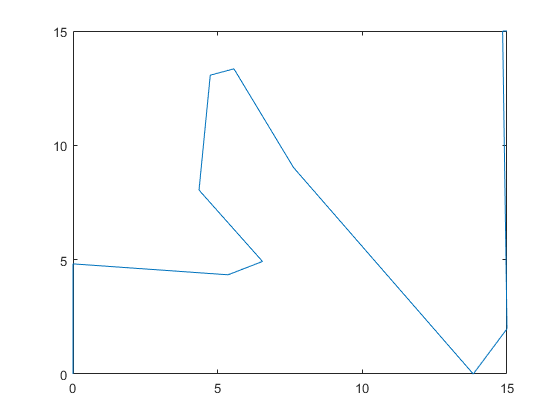

    plot([Po(1), Ciudades(1, Elite(1, :)), Pf(1)], [Po(2), Ciudades(2, Elite(1, :)), Pf(2)])